# Inverted Pendulum Dynamics

close all
clear all
clc
global A;
global B;
global u;
A = [0 1 0 0; 0 -0.1818 2.6727 0; 0 0 0 1; 0 -0.4545 31.1818 0];
B = [0; 1.8182; 0; 4.5455];


dt = 0.1;
% Create state space model
%sys = ss(A,B,[],[]);
% Convert to discrete, where dt is your discrete time-step (in seconds)
% d_sys = c2d(sys,dt);

[Ad, Bd] = LTI_translation(A,B,dt);

# Simulation Settings

x0 = [0.5; 1; pi/4; -1];    % initial condition
xr = [0; 0; pi/2; 0];      % reference position

# Recovery

k = 128;
initial_set_lo = x0;
initial_set_up = x0;
errorbound = [100; 0.1; 0.1; 0.1];
target_set_lo = xr - errorbound;
target_set_up = xr + errorbound;

utemp = recovery_control(Ad, Bd, k, initial_set_lo, initial_set_up, target_set_lo, target_set_up);

Aeq =    -1.0000   -0.0991   -0.0136   -0.0005    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.9818   -0.2789   -0.0136         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

beq =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


A =     -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0    -1     0     0     0     0     0     0     0     0     0     0     0   

b =    -0.5000
   -1.0000
   -0.7854
    1.0000
    0.5000
    1.0000
    0.7854
   -1.0000
  100.0000
    0.1000


Optimal solution found.



result =     0.5000
    1.0000
    0.7854
   -1.0000
    0.7648
    4.3048
    1.2000
    9.4813
    1.0303
    1.0460


inputs = utemp((length(utemp)-k+1):end);

# Simulator 

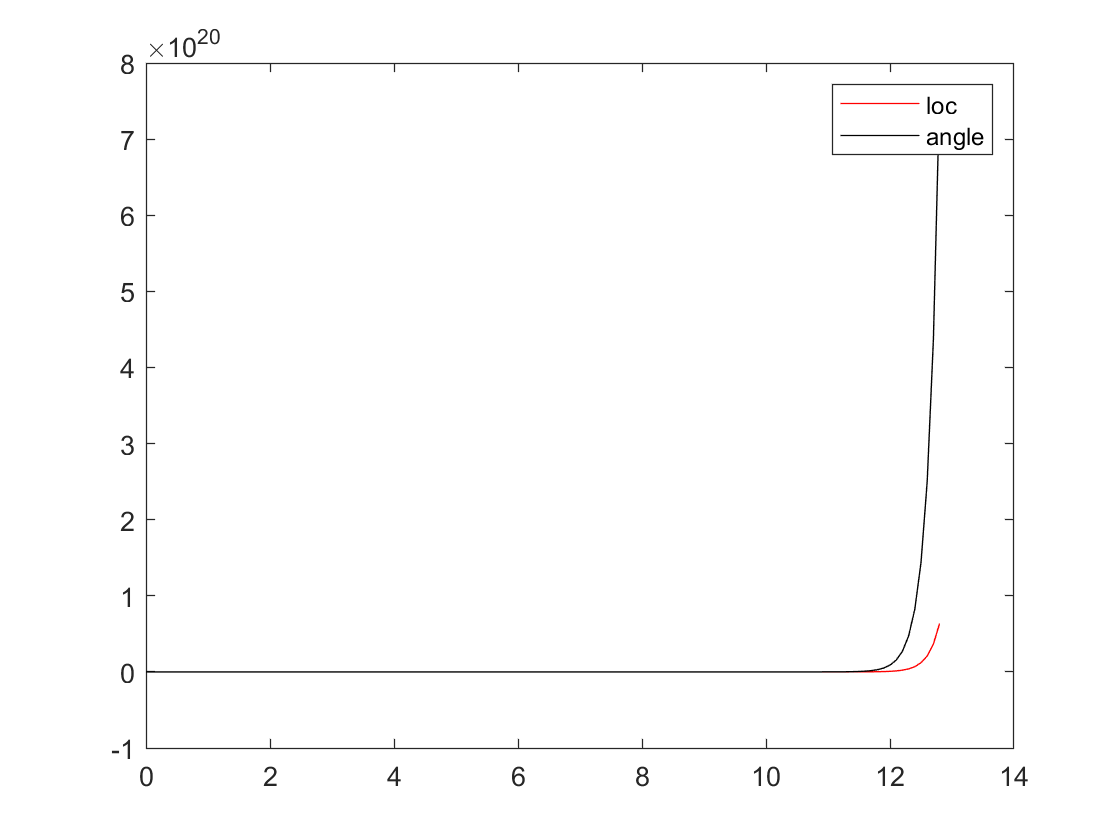

result = x0';
x = x0;
t_span = 0:dt:dt*k;

for i=1:k
   u = inputs(i);
   [T y] = ode45(@dynamics, [0 dt], x);
   result = [result; y(end,:)];
   x = y(end,:)';
end

plot(t_span,result(:,1),'r',t_span,result(:,3),'k')
legend('loc','angle')

function dxdt = dynamics(t, x)

global A;
global B;
global u;

dxdt = A*x + B*u;

end

